# Car Motion Control to Avoid Obstacles with Fuzzy Logic Controller

## Problem Description

We are given a 2D space consisting of a car (dimensionless) and an obstacle (Fig. 1). Given an initial position of the car, and the position of the obstacle, our task is to control the car and 'drive' it towards the given coordinates in that 2D space avoiding collision.

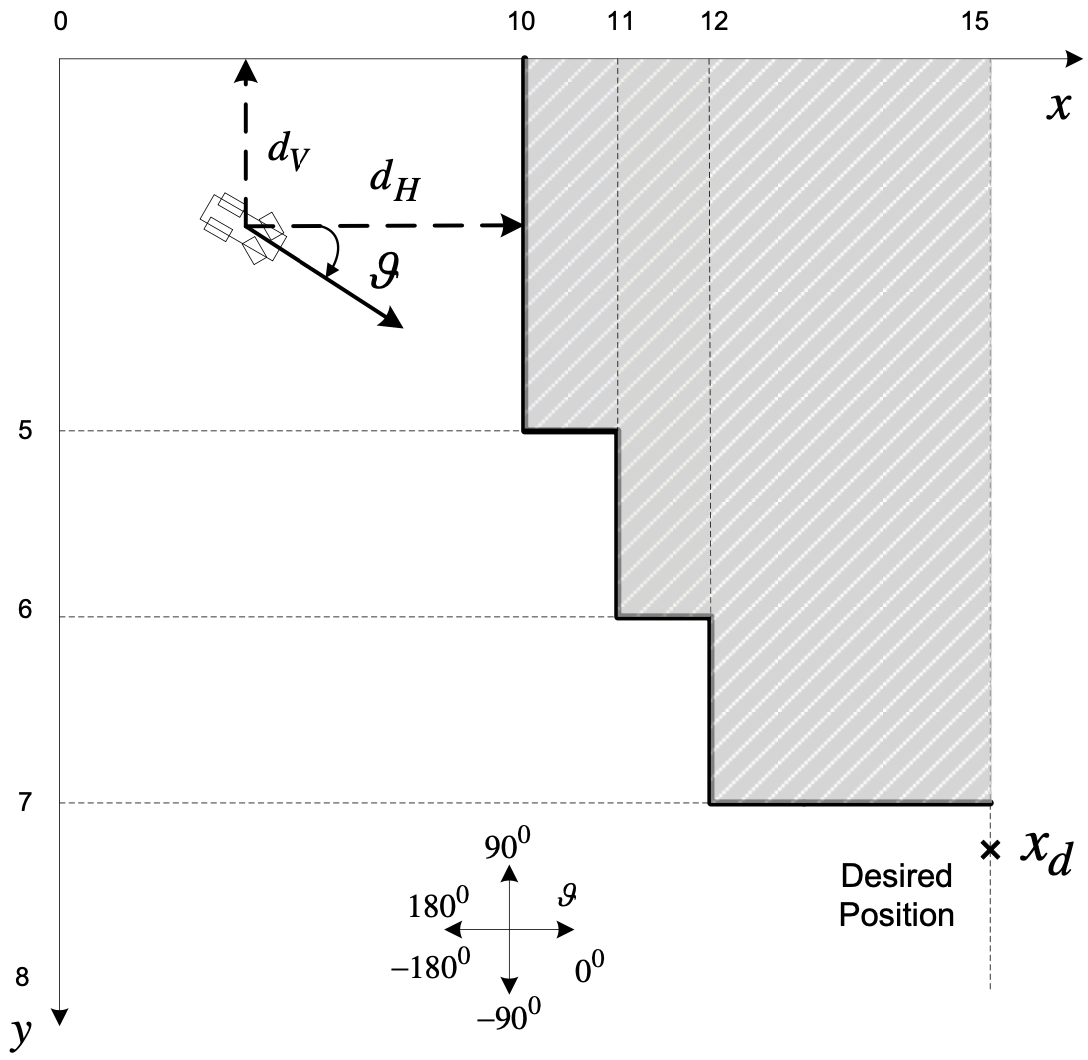

Fig. 1 Initial 2D space

The car 'has' sensors that constantly calculate the vertical $d_V$ and the horizontal $d_H$ distance from the obstacle. We are given that the car's speed is constant at $u=0\ldotp 05\;\frac{m}{s}$ and that the initial direction of the car is also given $[0\degree, 45\degree, 90\degree]
$. The car's starting point is: $\left(x_{\textrm{init}} ,y_{\textrm{init}} \right)=\left(9,4\ldotp 4\right)$ and the goal is to move it towards the $\left(x_d ,y_d \right)=\left(15,7\ldotp 2\right)$. It's important that the car arrives at the given $x_d$ and as close as possible to $y_d$.

We are asked to design an FLC that, knowing the $d_V$ and $d_H$ distance from the obstacle as well as the initial direction $\theta$ of the car, decides the alteration of the angle $d\theta$ in order to get the car to the given end coordinates $\left(x_d ,y_d \right)$.

So we must design the FLC having as inputs the distances and given initial angle, and as output the alteration of the angle according to the set below (Fig. 2).

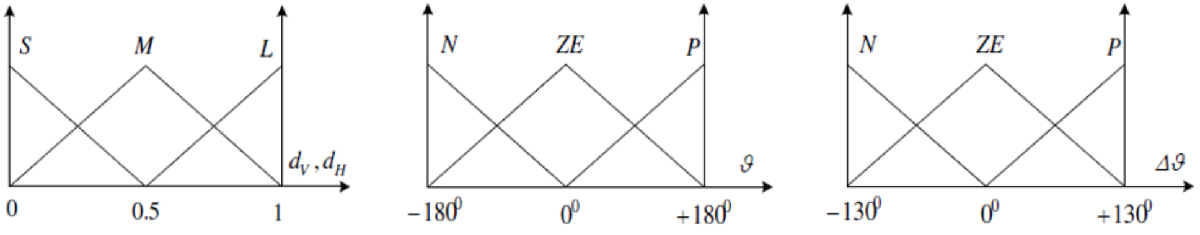

Fig. 2 Fuzzy variables

The rulebase must be designed based on rules that look like: 

Fig. 3 Rulebase sentence

## Fuzzy Logic Controller

The FLC was created based on the instructions and through a lengthy trial and error process, and it is created by the script *rulebase.m*.

clc; clearvars; close all;
addpath("lib")
addpath("/lib/flcs")
% Uncomment below to create again the fis and the rulebase
% run rulebase.m
FLC = readfis('lib/flcs/FLC') 

FLC =   mamfis with properties:

                       Name: "FLC"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×27 fisrule]

	See 'getTunableSettings' method for parameter optimization.


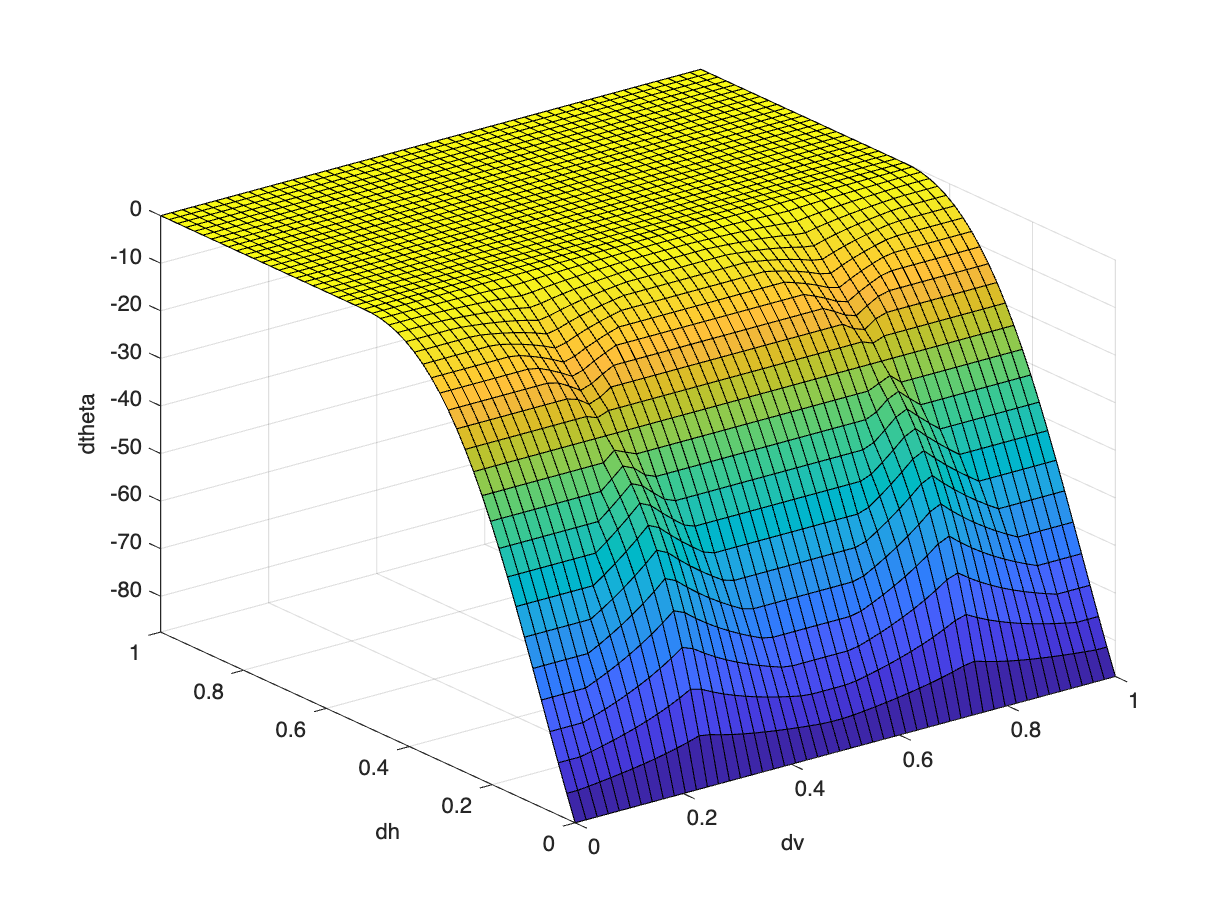

figure; 
options = gensurfOptions('NumGridPoints', 50);
gensurf(FLC, options)

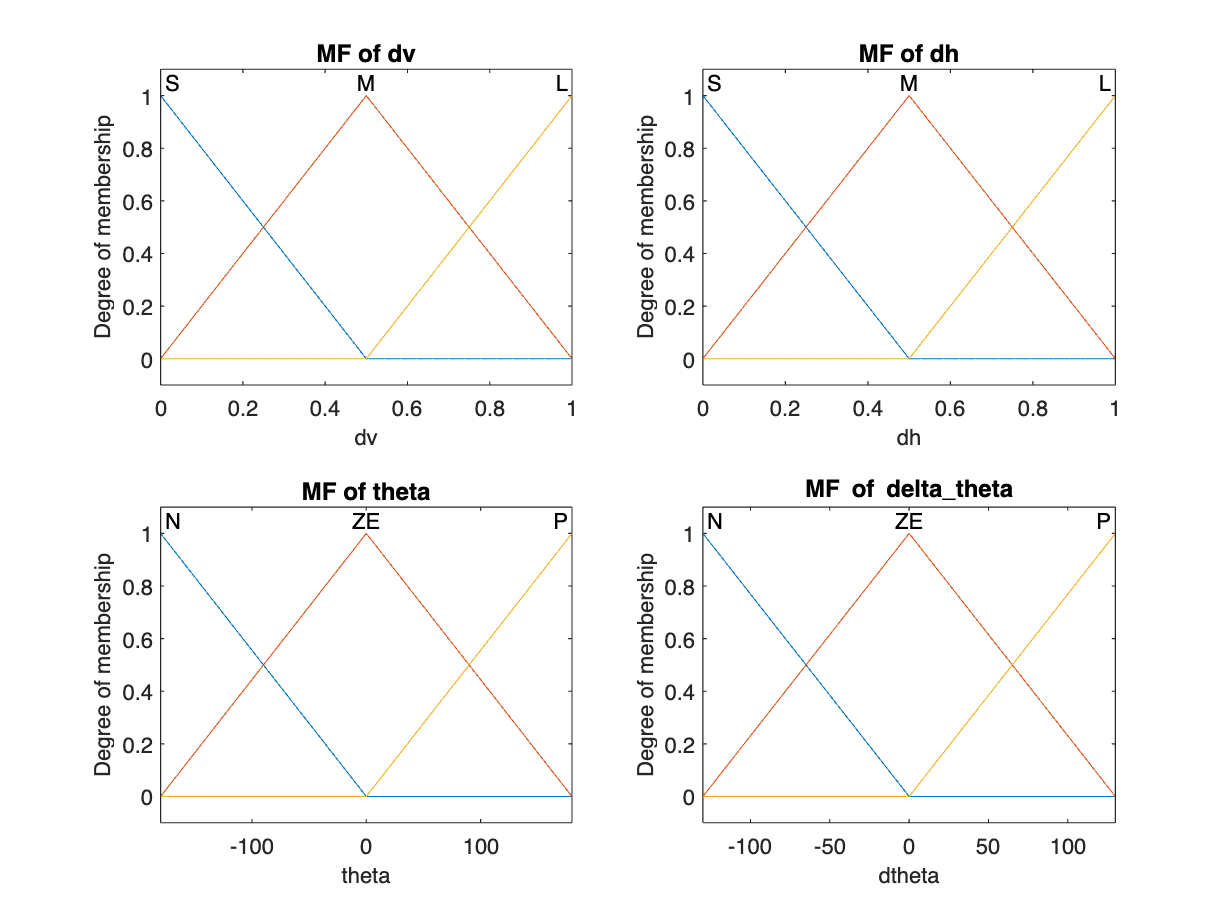

% Plot membership functions
figure;
subplot(2,2,1)
plotmf(FLC, 'input', 1);
title('MF of dv');

subplot(2,2,2)
plotmf(FLC, 'input', 2);
title('MF of dh');

subplot(2,2,3)
plotmf(FLC, 'input', 3);
title('MF of theta');

subplot(2,2,4)
plotmf(FLC, 'output', 1);
title('MF of delta\_theta');

## Creating 2D space

In order to test the car's ability to perform the given task, we must first initialize the environment.

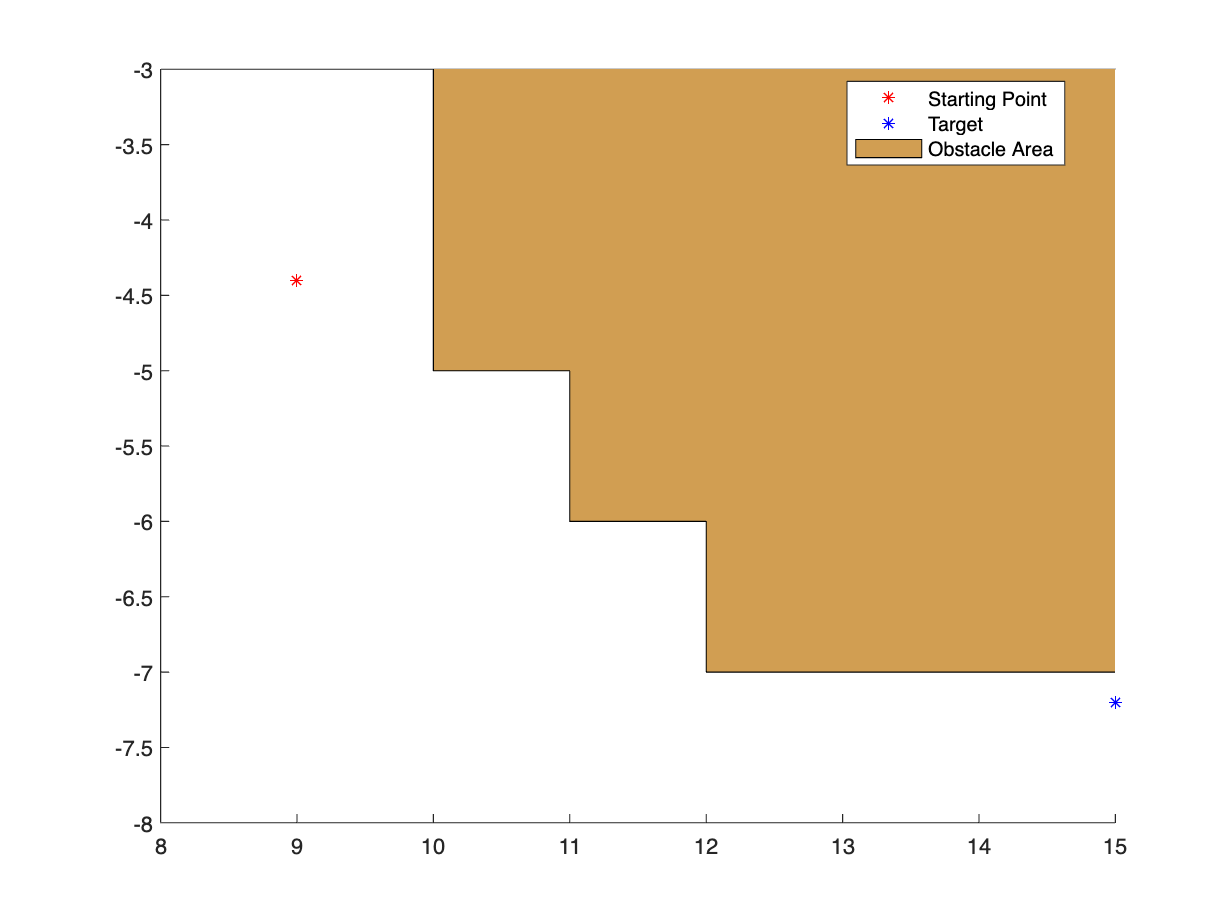

warning('off','all')

% Obstacle's position
obstacle = [10 0 ; 10 -5 ;11 -5 ; 11 -6 ; 12 -6 ; 12 -7 ; 15 -7];

% Car's position intialization
x_init = 9;
y_init = -4.4;
u = 0.05; % Speed
thetas = [0 45 90]; % The three variations of the car's starting direction

% Target coordinates
x_desired = 15;
y_desired = -7.2;
threshold = 0.1; % Allowed deviation/error from y_desired

figure();
hold on;
axis([8 15 -8 -3]);
plot(x_init, y_init, "r*", 'DisplayName', 'Starting Point');
plot(x_desired, y_desired, "b*", 'DisplayName', 'Target');
a = area(obstacle(:,1),obstacle(:,2), 'DisplayName','Obstacle Area');
set(a, 'FaceColor', '#D19E52');
legend('Location', 'Best');

## Simulating car's route

We must now create the the functions that will drive the car. First we will need a way to measure the distance of the car from the obstacle at any given time, and another for driving and 'maneuvering' it, utilizing the FLC to turn the car. 

In the *vertical_distance.m *and *horizontal_distance.m *we have created two functions which given the current coordinates, they calculate the vertical and horizontal distance from the obstacle.

We then proceeded in creating the function which will simulate the driving in *simulateRoute.m*. It utilizes the FLC and and the functions above, to calculate its current position and evaluate the required 'turning' of the car in order to avoid the obstacle whilst getting to the desired position. It also checks whether the car has remained within the map and calculates the distance from the end coordinates so that it can stop running the simulation.

Finally, we need a way to visualize the movement, thus we created the *plotMap.m*. 

We are now ready to simulate the car's movement, iterating through the 3 starting directions (thetas).

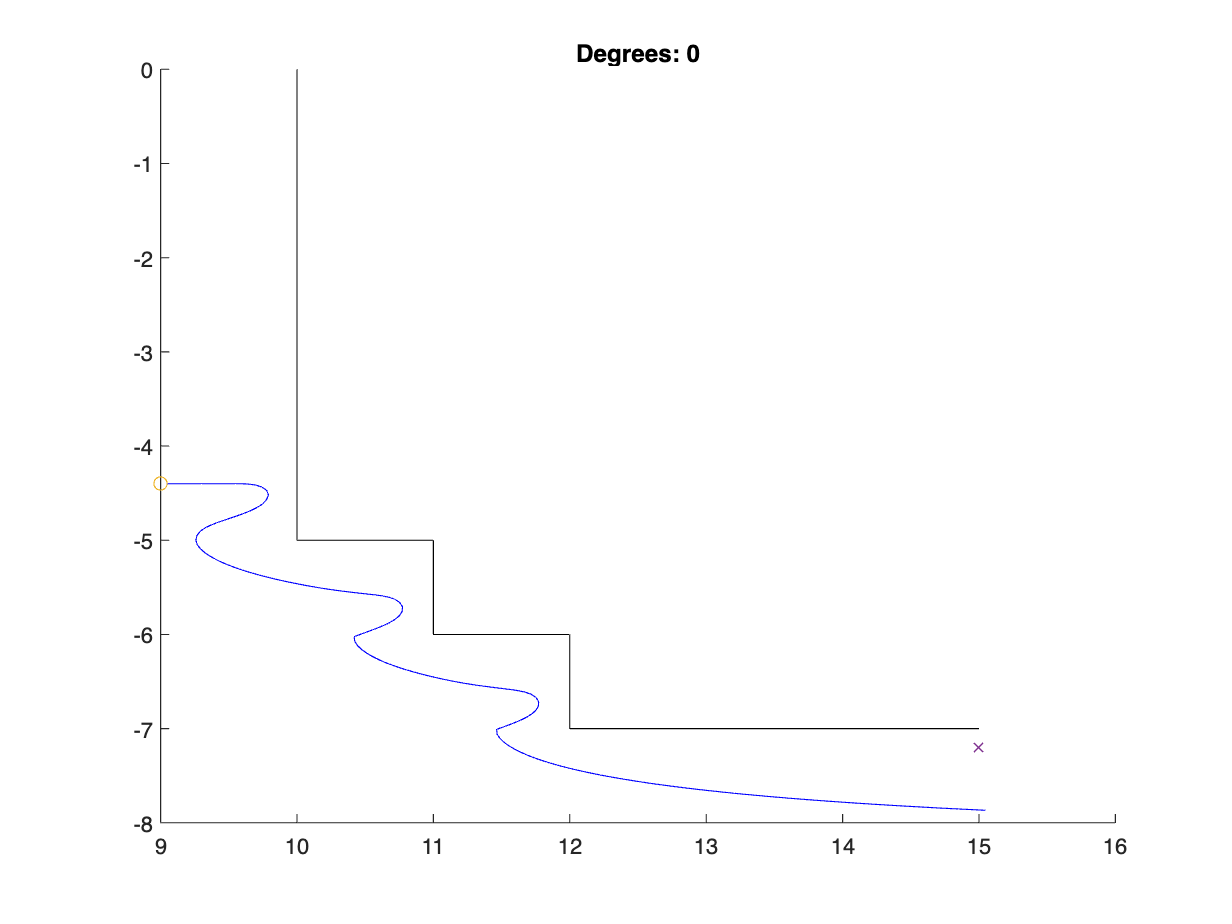

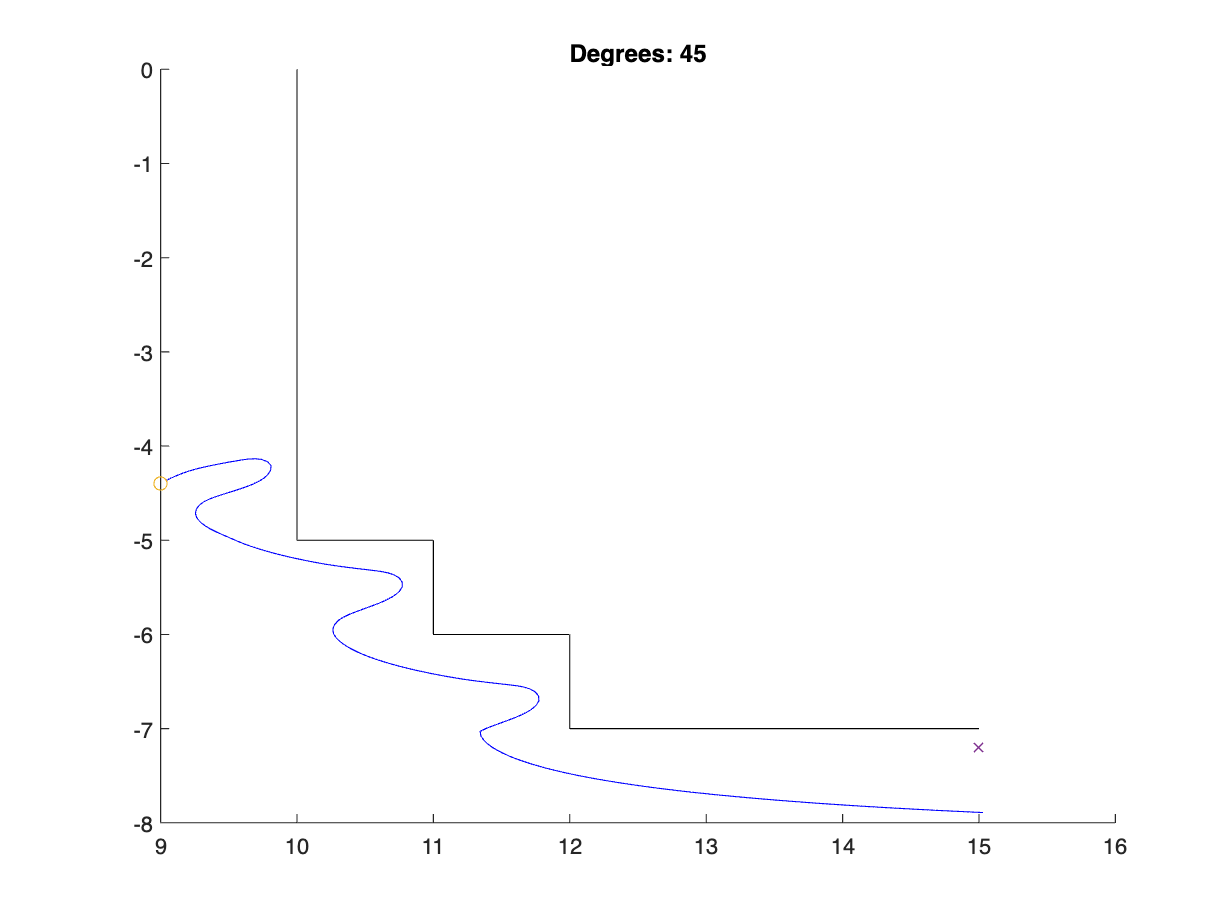

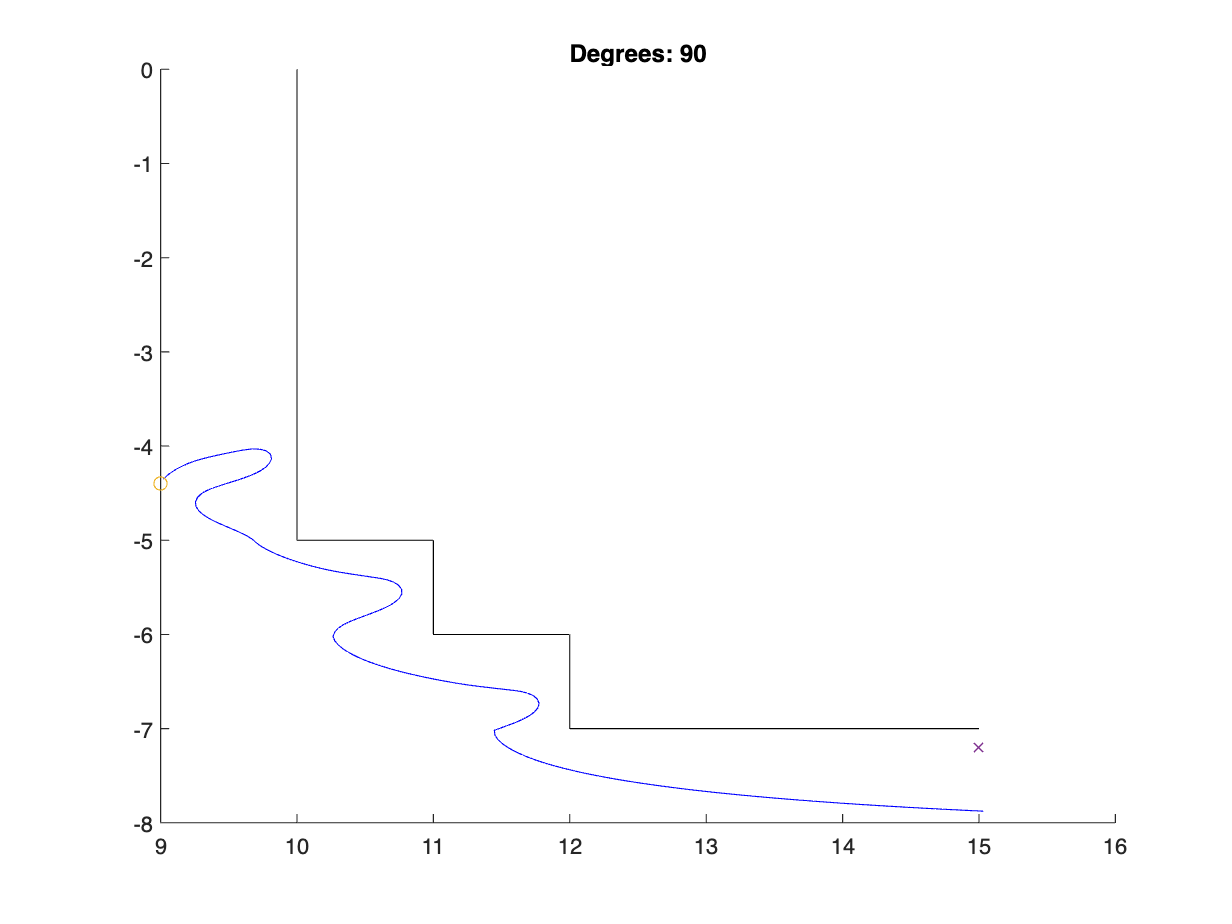

% Route Simulation
for i = 1 : 1 : length(thetas)
   [x_moves, y_moves, inMap, isClose] = simulateRoute(x_init, y_init, thetas(i), u, x_desired, y_desired, threshold, FLC);

   % Creating Map
   plotMap(x_moves, y_moves, x_init, y_init, x_desired, y_desired, thetas(i));
end

## Optimizing the FLC

We can see that given the initial instructions on how to build the fuzzy, we have a slight deviation from the desired end coordinates. To mitigate that, we must modify the FLC in order to better approach our goal.

For that, we updated the rulebase and created another file *rulebase_optimized.m* as an attempt towards that, after significant effort of trying different combinations of membership functions.

% Uncomment below to create again the optimal fis and the rulebase
% run opt_rulebase.m
optFLC = readfis('lib/flcs/optFLC')

optFLC =   mamfis with properties:

                       Name: "optFLC"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "prod"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
    DisableStructuralChecks: 0
                     Inputs: [1×3 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×27 fisrule]

	See 'getTunableSettings' method for parameter optimization.


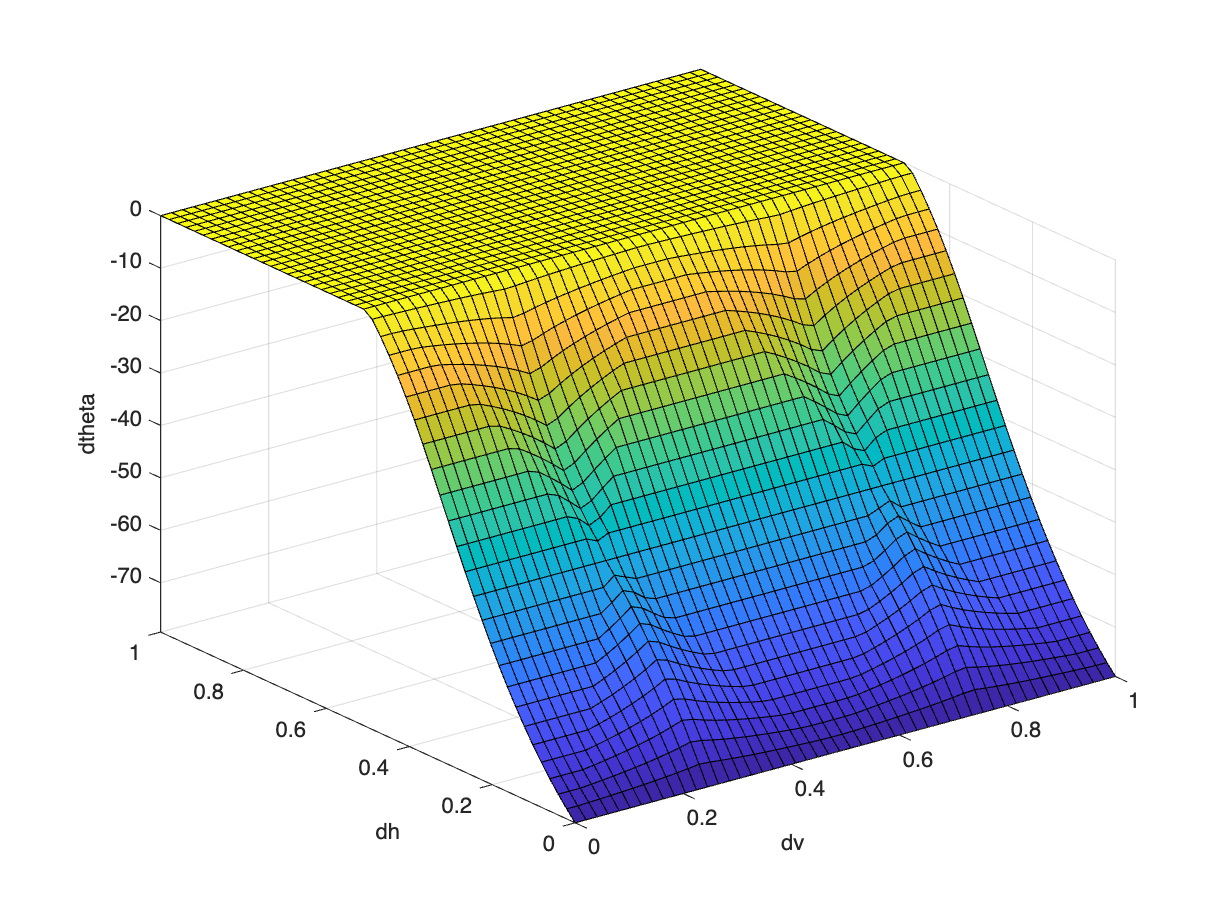

figure; 
options = gensurfOptions('NumGridPoints', 50);
gensurf(optFLC, options)

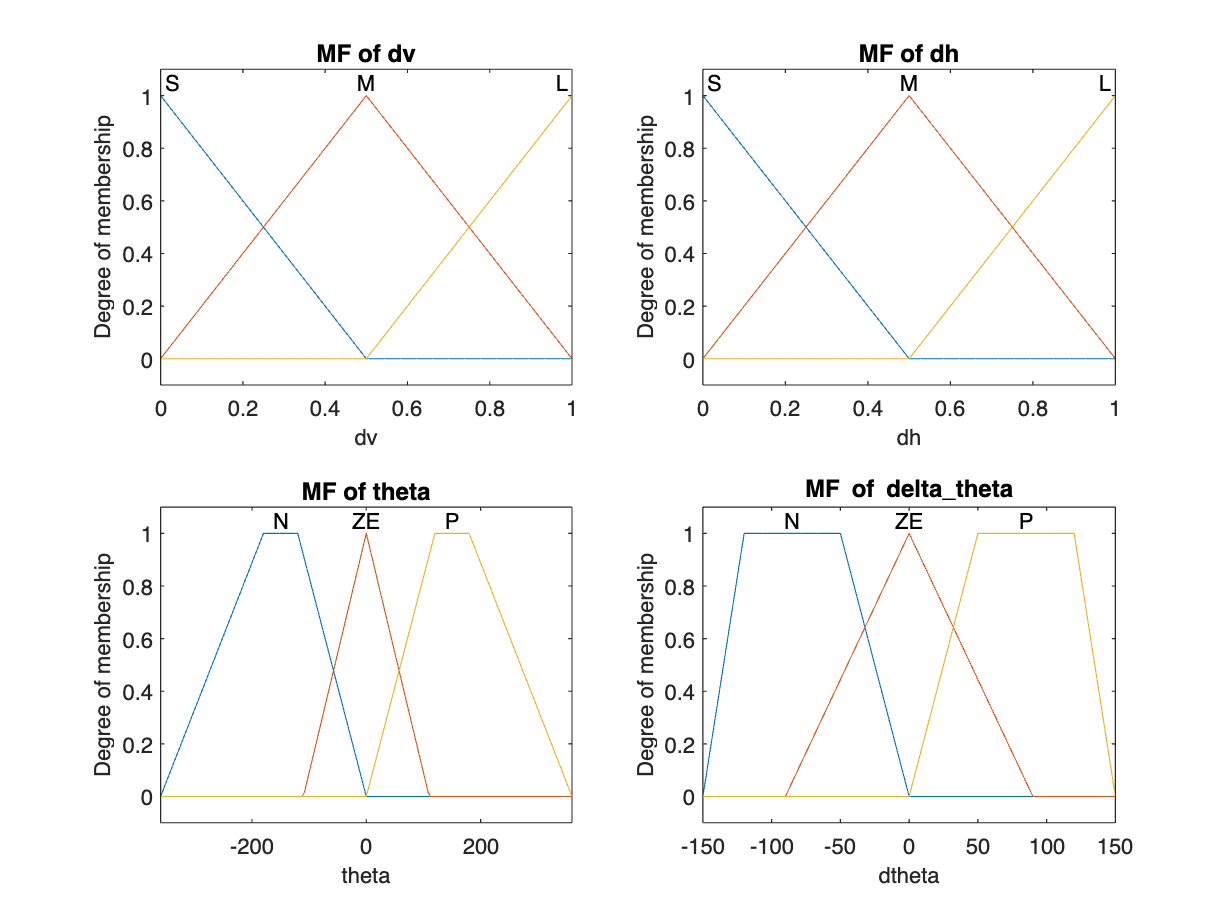

% Plot membership functions
figure;
subplot(2,2,1)
plotmf(optFLC, 'input', 1);
title('MF of dv');

subplot(2,2,2)
plotmf(optFLC, 'input', 2);
title('MF of dh');

subplot(2,2,3)
plotmf(optFLC, 'input', 3);
title('MF of theta');

subplot(2,2,4)
plotmf(optFLC, 'output', 1);
title('MF of delta\_theta');

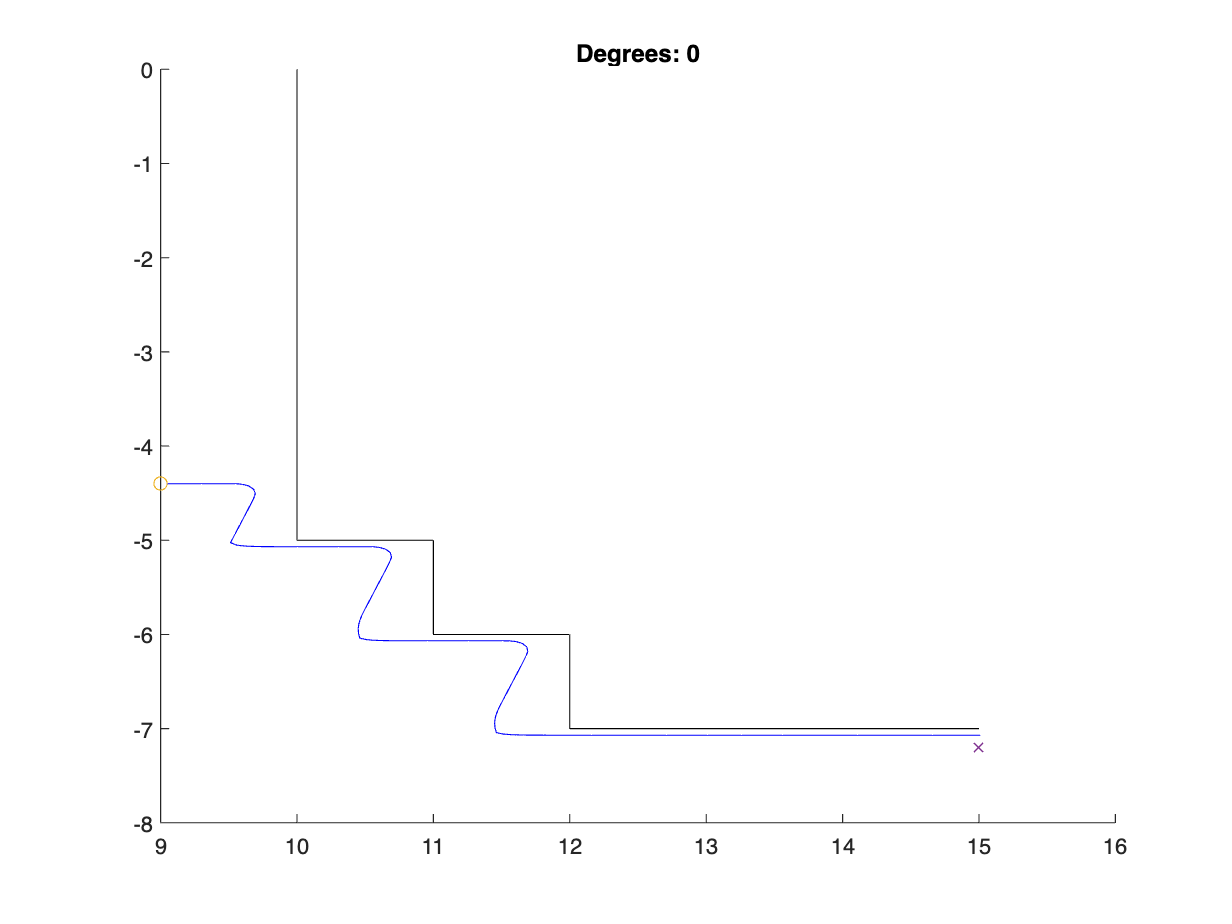

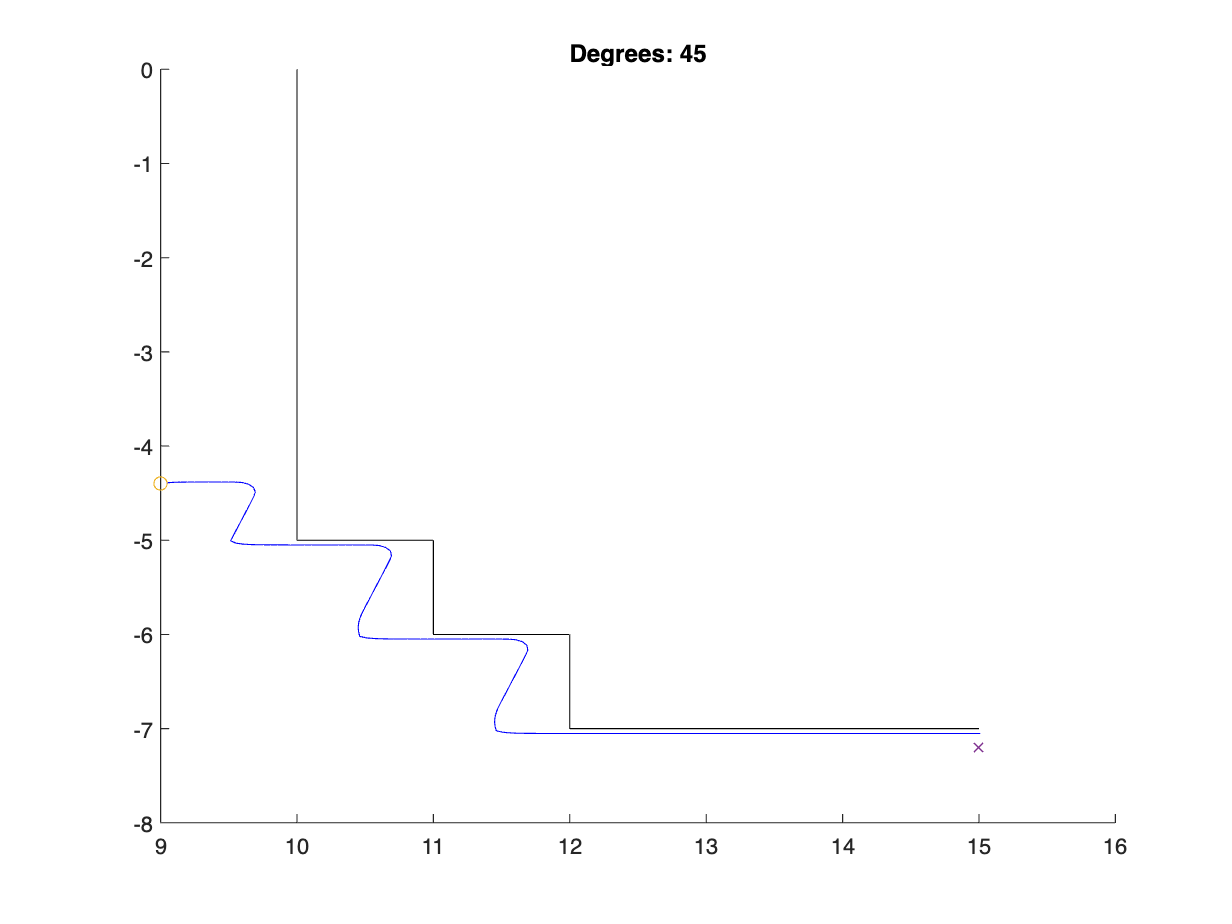

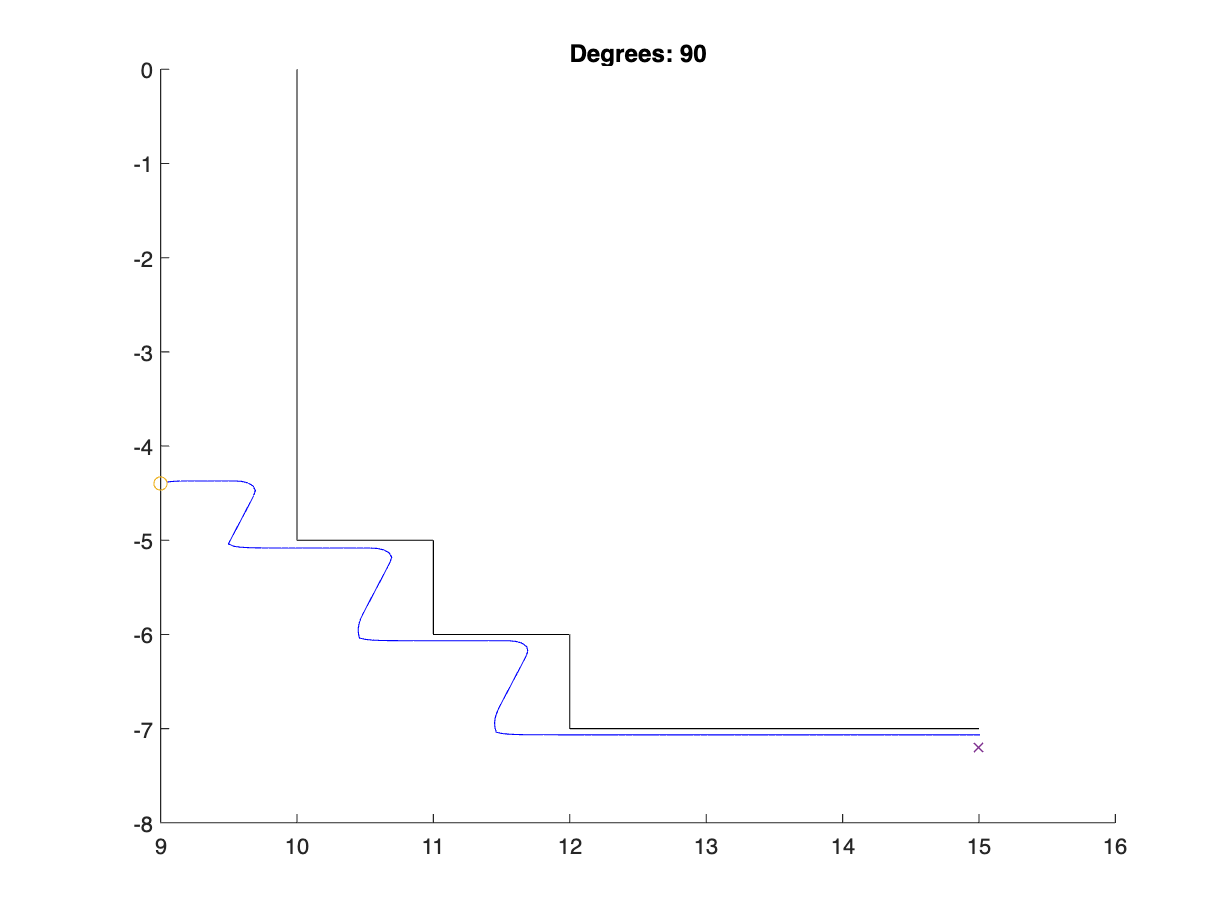

% Route Simulation
for i = 1 : 1 : length(thetas)
   [x_moves, y_moves, inMap, isClose] = simulateRoute(x_init, y_init, thetas(i), u, x_desired, y_desired, threshold, optFLC);

   % Creating Map
   plotMap(x_moves, y_moves, x_init, y_init, x_desired, y_desired, thetas(i));
end

As we can see, the car comes way closer to the desired coordinates and is seen to be moving closer to the barrier, having a 'faster' response in turning the car's direction whilst still avoiding succesfully the obstacle. This process of fine tuning the FLC required the understanding of the problem and how the parameters affect the system, so that they can be tuned. Even after that, a series of tries had to occur before arriving to an acceptable result.